# BL.SC.U4CSE24025 :- LAB2

## Q1

x =- 3:0.1:3;
y=x;
[x1,y1]=meshgrid(x,y);
z=x1.^2+y1.^2;
surf(x1,y1,z)
maximaMask=imregionalmax(z);
minimaMask=imregionalmin(z);
hold on;
plot3(x1(maximaMask),y1(maximaMask),z(maximaMask),'r.','MarkerSize',20);
plot3(x1(minimaMask),y1(minimaMask),z(minimaMask),'r.','MarkerSize',20);
hold off;
title("Local Maxima and Minima");
xlabel("X")
ylabel("Y")
zlabel("Z")

## Q2

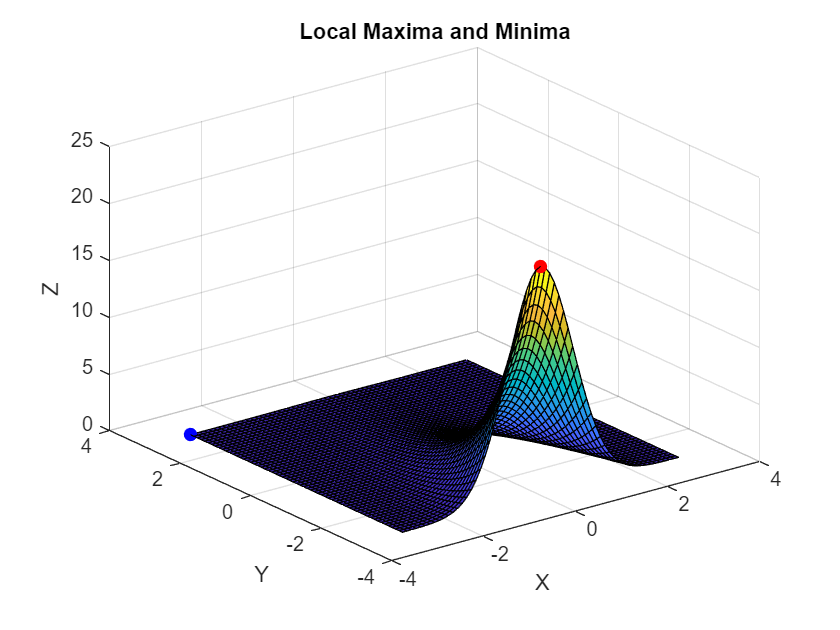

clc;
clear all;
x =- 3:0.1:3;
y=x;
[x1,y1]=meshgrid(x,y);
z1=exp(-(x1.^2+y1));
[maxZ,maxIndex]=max(z1(:));
[minZ,minIndex]=min(z1(:));
[maxRow,maxCol]=ind2sub(size(z1),maxIndex);
[minRow,minCol]=ind2sub(size(z1),minIndex);
figure;
surf(x1,y1,z1);
hold on;
plot3(x1(maxRow,maxCol),y1(maxRow,maxCol),maxZ,'r.','MarkerSize',20);
plot3(x1(minRow,minCol),y1(minRow,minCol),minZ,'b.','MarkerSize',20);
hold off;
title("Local Maxima and Minima");
xlabel("X")
ylabel("Y")
zlabel("Z")

## Q3

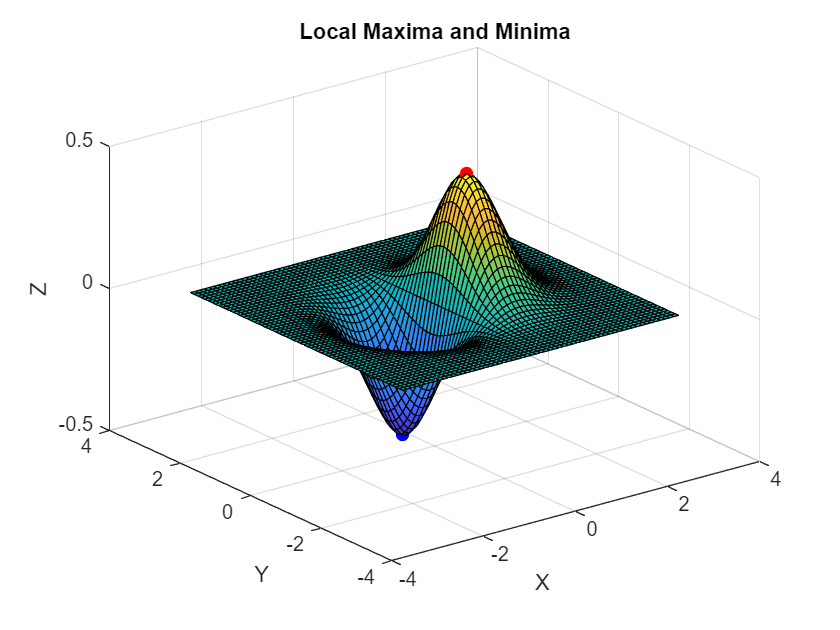

clc;
clear all;
x =- 3:0.1:3;
y=x;
[x1,y1]=meshgrid(x,y);
z2=x .* exp(-(x1.^2+y1.^2));
[maxZ, maxIndex]=max(z2(:));
[minZ,minIndex]=min(z2(:));
[maxRow,maxCol]=ind2sub(size(z2),maxIndex);
[minRow,minCol]=ind2sub(size(z2),minIndex);
figure;
surf(x1,y1,z2);
hold on;
plot3(x1(maxRow,maxCol),y1(maxRow,maxCol),maxZ,'r.','MarkerSize',20);
plot3(x1(minRow,minCol),y1(minRow,minCol),minZ,'b.','MarkerSize',20);
hold off;
title("Local Maxima and Minima");
xlabel("X")
ylabel("Y")
zlabel("Z")

## Q4

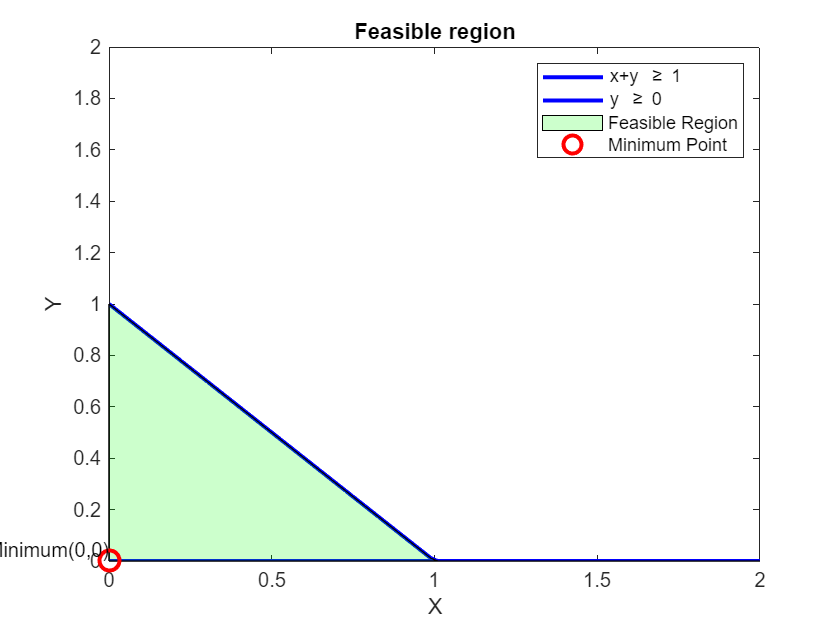

clc;
clear all;
x=linspace(0,2,100);
y1=max(0,1-x);
y2=zeros(size(x));
figure;
plot(x,y1,'b','LineWidth',2);
hold on;
plot(x,y2,'b','LineWidth',2);
xlabel("X")
ylabel("Y")
title("Feasible region");
ylim([0,2]);

fill([x,fliplr(x)],[y1,fliplr(y2)],'g','FaceAlpha',0.2);
objective=@(x,y) x.^2+y.^2;
[X,Y]=meshgrid(0:0.1:2,0:0.1:2);
Z=objective(X,Y);
Z((X+Y)>=1)= NaN;
[minZ,minIndex]=min(Z(:));
[minRow,minCol]=ind2sub(size(Z),minIndex);
minX=X(minRow,minCol);
minY=Y(minRow,minCol);
plot(minX,minY,'ro','MarkerSize',10,'LineWidth',2);
text(minX,minY,['Minimum(',num2str(minX),',',num2str(minY),')'],'VerticalAlignment','bottom', 'HorizontalAlignment','right');
xlabel("X")
ylabel("Y")
zlabel("Z")
legend('x+y \geq 1','y \geq 0','Feasible Region','Minimum Point');
hold off;

## Q5

clc;
fun=@(x)x(1)^2+x(2)^2;
x0=[0,0];
A=[-1,-1];
B =- 1;
lb=[0,0];
[x_opt, fval]=fmincon(fun,x0,A,B,[],[],lb,[]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


disp('Optimal Solution : ');

Optimal Solution : 


disp(['x=',num2str(x_opt(1)),',y=',num2str(x_opt(2))]);

x=0.5,y=0.5


disp(['Function value at optimum : ',num2str(fval)]);

Function value at optimum : 0.5


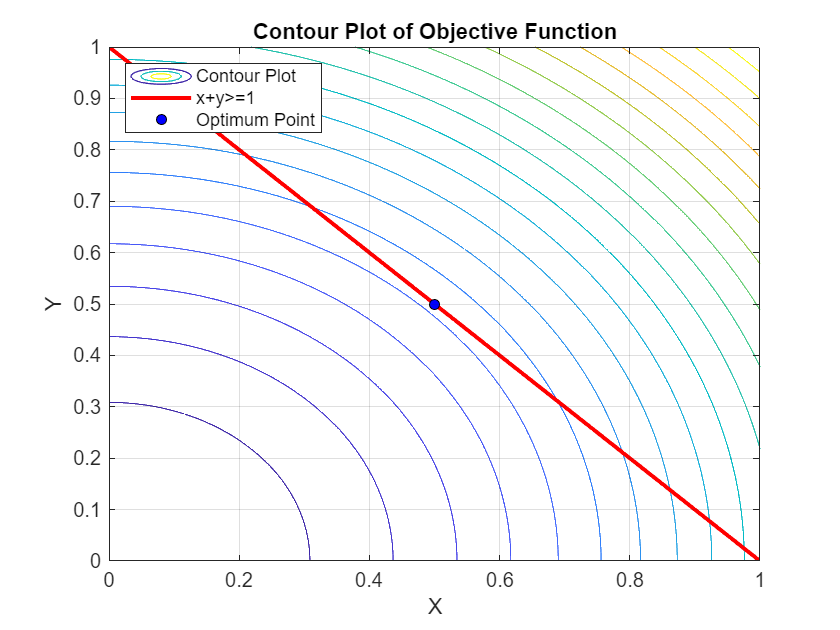

x=0:0.001:1;
y=0:0.001:1;
[X,Y]=meshgrid(x,y);
Z=X.^2+Y.^2;
contour(X,Y,Z,20);
hold on;
plot(x,1-x,'r','LineWidth',2);
plot(x_opt(1),x_opt(2),'ko','MarkerSize',5,'MarkerFaceColor','b');
xlabel("X");
ylabel("Y");
title("Contour Plot of Objective Function");
legend('Contour Plot','x+y>=1','Optimum Point','Location','northwest');
grid on;
hold off;

## Q6

clc;
x=0:0.1:1;
y=0:0.1:1;
fun=@(x)x(1)+x(2);
nonlcon=@(x) deal([],x(1)^2+x(2)^2-1);
x0=[0.5,0.5];
lb=[0,0];
[x_opt, fval]=fmincon(fun,x0, [],[],[],[],lb, [],nonlcon);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


disp('Optimal Solution');

Optimal Solution


disp(['x=',num2str(x_opt(1)),',y=',num2str(x_opt(2))]);

x=0.70711,y=0.70711


disp(['Minimum value of x+y at optimum : ',num2str(fval)]);

Minimum value of x+y at optimum : 1.4142


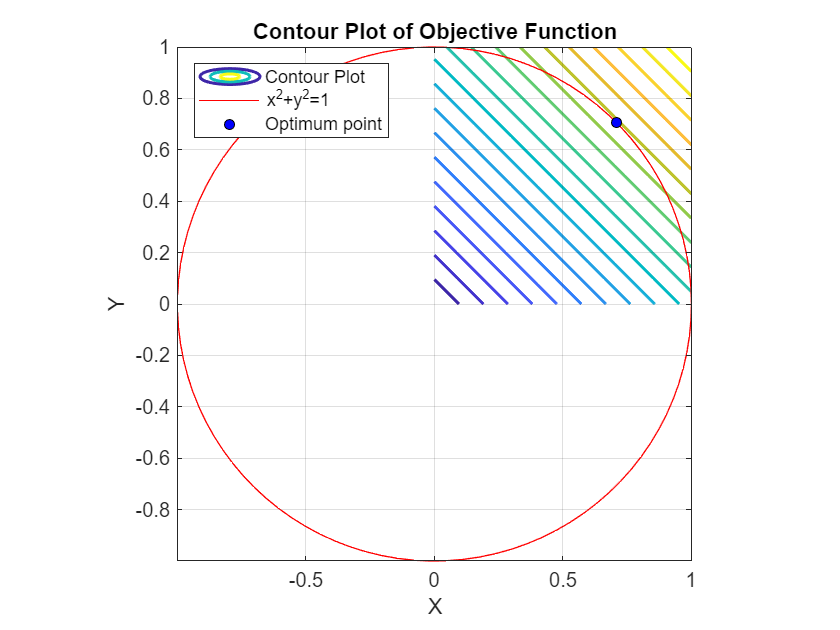

[X,Y]=meshgrid(x,y);
Z=X+Y;
contour(X,Y,Z,20,'LineWidth',1.5);
hold on;
theta=linspace(0,2*pi,100);
r=1;
x=r*cos(theta);
y=r*sin(theta);
plot(x,y,'r');
plot(x_opt(1),x_opt(2),'ko','MarkerSize',5,'MarkerFaceColor','b');
xlabel("X");
ylabel("Y");
title("Contour Plot of Objective Function");
legend('Contour Plot', 'x^2+y^2=1','Optimum point','location','northwest');
axis equal;
grid on;
hold off;

## Q7

clc;
fun=@(x)-(x(1)+x(2));
nonlcon=@(x) deal(x(1)^2+x(2)^2-25,[]);
x0=[0,0];
A=[-1,-1];
b =- 5;
lb=[0,0];
[x_opt, fval]=fmincon(fun,x0,A,b,[],[],lb,[],nonlcon);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fval =- fval;
disp("Optimal solution : ");

Optimal solution : 


disp(['x=',num2str(x_opt(1)),',y=',num2str(x_opt(2))]);

x=3.5355,y=3.5355


disp(['Maximum value of x+y at optimum : ',num2str(fval)]);

Maximum value of x+y at optimum : 7.0711


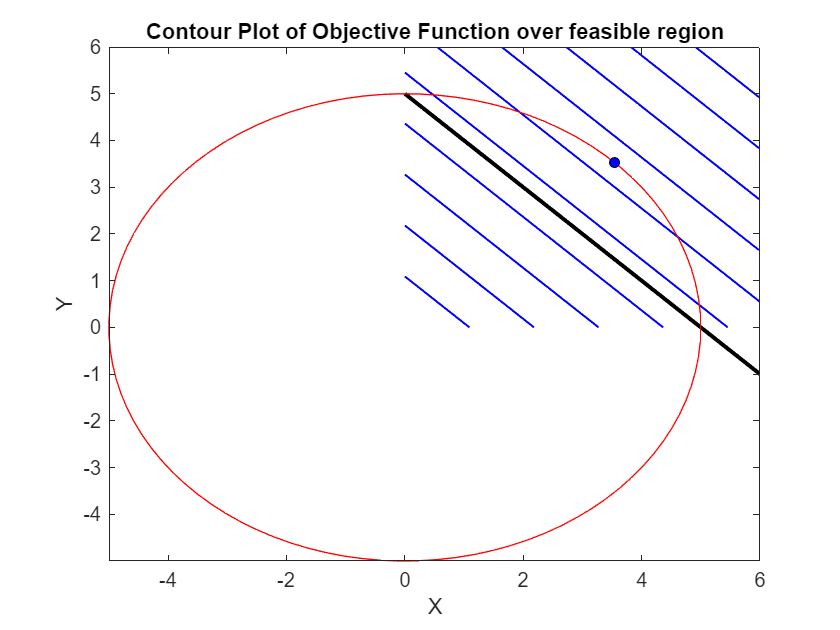

x=linspace(0,6,100);
y=linspace(0,6,100);
[X,Y]=meshgrid(x,y);
Z=X+Y;
contour(X,Y,Z,10,'b','LineWidth',1);
hold on;
plot(x,5-x,'black','LineWidth',2);
theta=linspace(0,2*pi,100);
r=5;
x=r*cos(theta);
y=r*sin(theta);
plot(x,y,'r');
plot(x_opt(1),x_opt(2),'ko','MarkerSize',5,'MarkerFaceColor','b');
xlabel("X");
ylabel("Y");
title('Contour Plot of Objective Function over feasible region');

## Q8

clc;
clf;
clear all;

fun=@(x)x(1)+x(2);
nonlcon=@(x) deal(x(1)^2+x(2)^2-25,[]);
x0=[0,0];
A=[-1,-1];
b =- 5;
lb=[0,0];
[x_opt, fval]=fmincon(fun,x0,A,b,[],[],lb,[],nonlcon);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



fval =- fval;
disp("Optimal solution : ");

Optimal solution : 


disp(['x=',num2str(x_opt(1)),',y=',num2str(x_opt(2))]);

x=2.5,y=2.5


disp(['Maximum value of x+y at optimum : ',num2str(fval)]);

Maximum value of x+y at optimum : -5


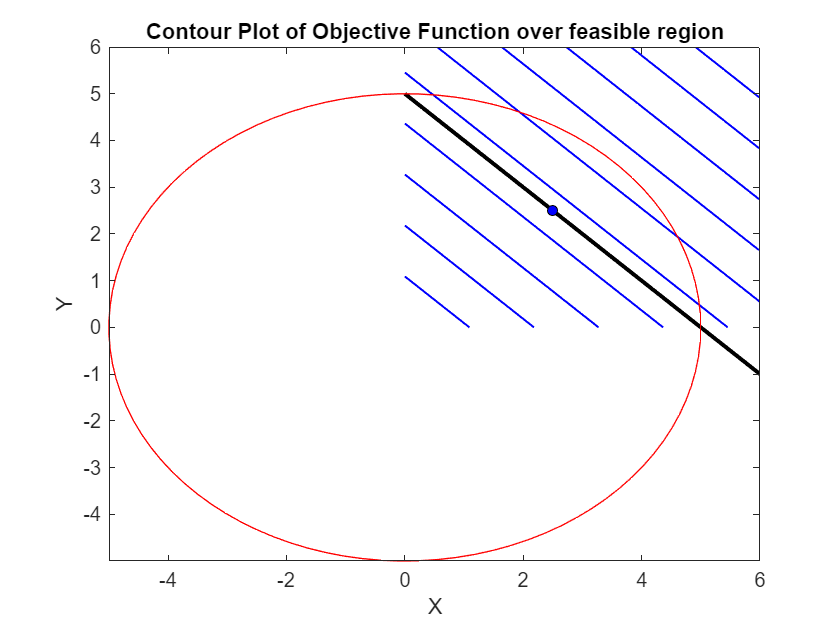


x=linspace(0,6,100);
y=linspace(0,6,100);
[X,Y]=meshgrid(x,y);
Z=X+Y;
contour(X,Y,Z,10,'b','LineWidth',1);
hold on;
plot(x,5-x,'black','LineWidth',2);
theta=linspace(0,2*pi,100);
r=5;
x=r*cos(theta);
y=r*sin(theta);
plot(x,y,'r');
plot(x_opt(1),x_opt(2),'ko','MarkerSize',5,'MarkerFaceColor','b');
xlabel("X");
ylabel("Y");
title('Contour Plot of Objective Function over feasible region');

## Practice questions

## Question 1

clc;
x = 0:0.1:10;
y = 0:0.1:10;
fun = @(x) - (x(1) + x(2));
A = [0 1; 1 1];
b = [5; 10];
x0 = [1, 1];
lb = [0, 0];
[x_opt, fval] = fmincon(fun, x0, A, b, [], [], lb, []);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


disp('Optimal Solution');

Optimal Solution


disp(['x = ', num2str(x_opt(1)), ', y = ', num2str(x_opt(2))]);

x = 6.5496, y = 3.4504


disp(['Maximum value of x + y at optimum: ', num2str(-fval)]);

Maximum value of x + y at optimum: 10


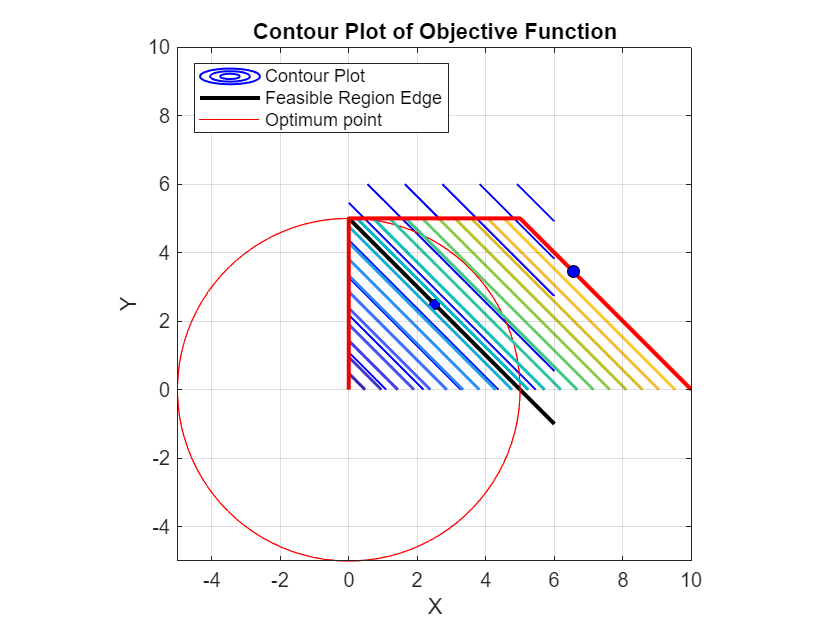

[X, Y] = meshgrid(x, y);
Z = X + Y;
Z(Y > 5 | (X + Y) > 10) = NaN;
contour(X, Y, Z, 20, 'LineWidth', 1.5);
hold on;
plot([0 0 5 10], [0 5 5 0], 'r', 'LineWidth', 2);
plot(x_opt(1), x_opt(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'b');
xlabel("X");
ylabel("Y");
title("Contour Plot of Objective Function");
legend('Contour Plot', 'Feasible Region Edge', 'Optimum point', 'Location', 'Northwest');
axis equal;
grid on;
hold off;

## Question 2

clc;
x = 0:0.1:10;
y = 0:0.1:10;
fun = @(v) -3 * v(2);
A = [1 0; -1 1; 1 1];
b = [3; 4; 6];
x0 = [1, 1];
lb = [0, 0];
[x_opt, fval] = fmincon(fun, x0, A, b, [], [], lb, []);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


disp('Optimal Solution');

Optimal Solution


disp(['x = ', num2str(x_opt(1)), ', y = ', num2str(x_opt(2))]);

x = 1, y = 5


disp(['Maximum value of 3y at optimum: ', num2str(-fval)]);

Maximum value of 3y at optimum: 15


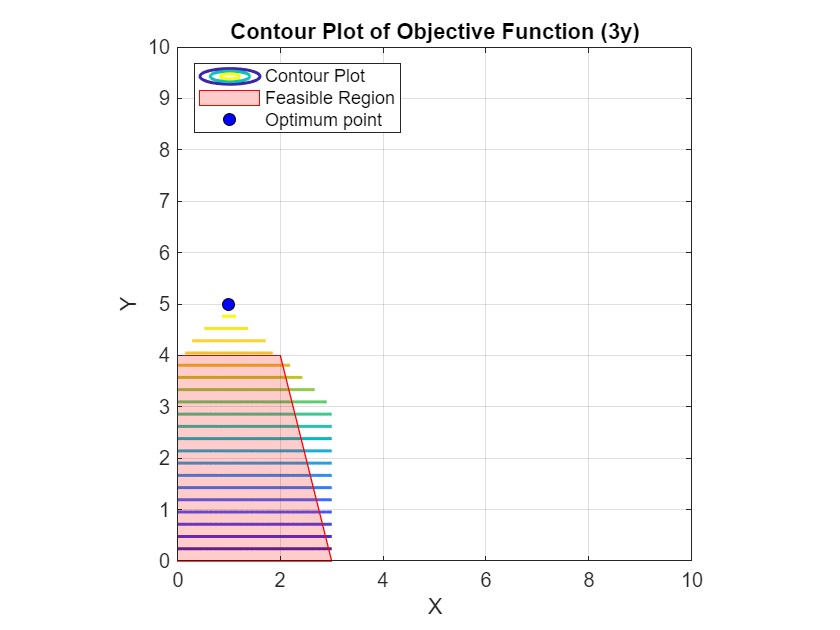

[X, Y] = meshgrid(x, y);
Z = 3 * Y;
Z(X > 3 | -X + Y > 4 | X + Y > 6) = NaN;
contour(X, Y, Z, 20, 'LineWidth', 1.5);
hold on;
x1 = [0 3 2 0];
y1 = [0 0 4 4];
fill(x1, y1, 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'r');
plot(x_opt(1), x_opt(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'b');
xlabel("X");
ylabel("Y");
title("Contour Plot of Objective Function (3y)");
legend('Contour Plot', 'Feasible Region', 'Optimum point', 'Location', 'Northwest');
axis equal;
grid on;
hold off;

## Question 3

clc;
x = 0:0.1:10;
y = 0:0.1:10;
fun = @(v) - (v(1) + v(2));
A = [1 0; 0 1];
b = [3; 7];
x0 = [1, 1];
lb = [0, 0];
[x_opt, fval] = fmincon(fun, x0, A, b, [], [], lb, []);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


disp('Optimal Solution');

Optimal Solution


disp(['x = ', num2str(x_opt(1)), ', y = ', num2str(x_opt(2))]);

x = 3, y = 7


disp(['Maximum value of x + y at optimum: ', num2str(-fval)]);

Maximum value of x + y at optimum: 10


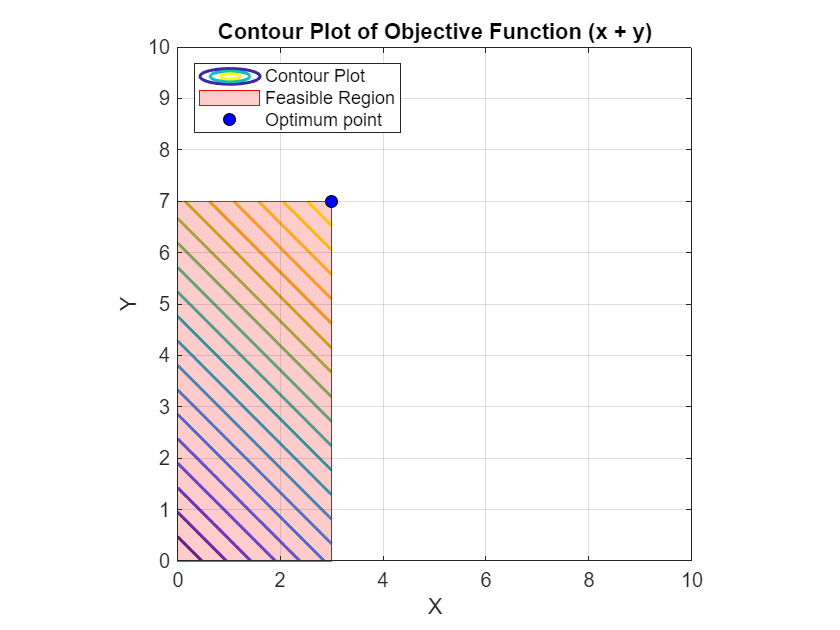

[X, Y] = meshgrid(x, y);
Z = X + Y;
Z(X > 3 | Y > 7) = NaN;
contour(X, Y, Z, 20, 'LineWidth', 1.5);
hold on;
x_rect = [0 3 3 0];
y_rect = [0 0 7 7];
fill(x_rect, y_rect, 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'r');
plot(x_opt(1), x_opt(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'b');
xlabel("X");
ylabel("Y");
title("Contour Plot of Objective Function (x + y)");
legend('Contour Plot', 'Feasible Region', 'Optimum point', 'Location', 'Northwest');
axis equal;
grid on;
hold off;

## Question 4

clc;
x = 0:0.1:3;
y = 0:0.1:7;
fun = @(v) v(1)^2 + v(2)^2;
neg_fun = @(v) -fun(v);
x0 = [1, 1];
A = [1 0; 0 1];
b = [3; 7];
lb = [0, 0];
[x_min, fminval] = fmincon(fun, x0, A, b, [], [], lb, []);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[x_max, fmaxval_neg] = fmincon(neg_fun, x0, A, b, [], [], lb, []);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fmaxval = -fmaxval_neg;
disp('Minimum at:');

Minimum at:


disp(['x = ', num2str(x_min(1)), ', y = ', num2str(x_min(2)), ', f = ', num2str(fminval)]);

x = 0.0006395, y = 0.00063953, f = 8.1796e-07


disp('Maximum at:');

Maximum at:


disp(['x = ', num2str(x_max(1)), ', y = ', num2str(x_max(2)), ', f = ', num2str(fmaxval)]);

x = 3, y = 7, f = 58


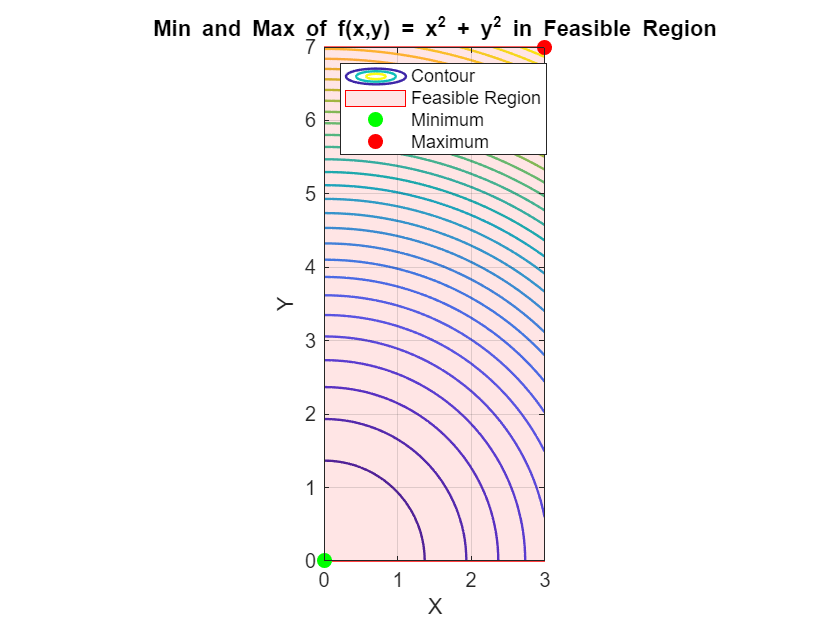

[X, Y] = meshgrid(x, y);
Z = X.^2 + Y.^2;
contour(X, Y, Z, 30, 'LineWidth', 1.2);
hold on;
fill([0 3 3 0], [0 0 7 7], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r');
plot(x_min(1), x_min(2), 'go', 'MarkerSize', 7, 'MarkerFaceColor', 'g');
plot(x_max(1), x_max(2), 'ro', 'MarkerSize', 7, 'MarkerFaceColor', 'r');
xlabel('X'); ylabel('Y');
title('Min and Max of f(x,y) = x^2 + y^2 in Feasible Region');
legend('Contour', 'Feasible Region', 'Minimum', 'Maximum', 'Location', 'Northwest');
axis equal;
grid on;
hold off;